## Plot Fig. S12: Mutual Information

## Load data


addpath(genpath('../public_code'))
nstrain = 'male_timp';


## Fig. S12 A



[mi2_bf_male, mi2_af_male] = load_data_compute_mi('male_timp');

mean_mi2_male = [mean(mi2_bf_male,2) mean(mi2_af_male,2)];


## Fig. S12 B


[mi2_bf_bsa, mi2_af_bsa] = load_data_compute_mi('male_bsa');

mean_mi2_bsa = [mean(mi2_bf_bsa,2) mean(mi2_af_bsa,2)];


## Fig. S12 C

[mi2_bf_female, mi2_af_female] = load_data_compute_mi('female_timp');

mean_mi2_female = [mean(mi2_bf_female,2) mean(mi2_af_female,2)];
mean_mi2_female_f5at = [mean(mi2_bf_female,2) mean(mi2_af_female(:,1:5),2)];


## Fig. S12 D

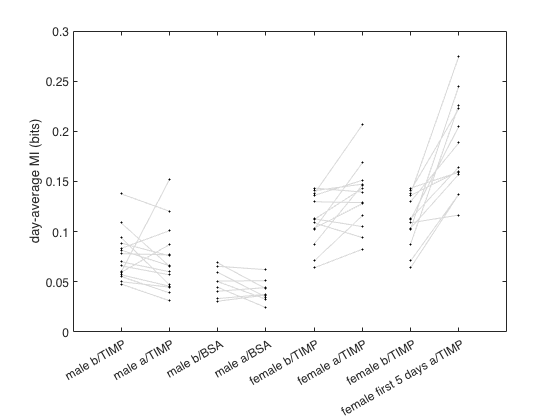

figure()
plot([1,2],mean_mi2_male','color',[0 0 0]+0.85,'linewidth',0.5)
hold on
plot([1,2],mean_mi2_male','k.')
plot([3,4],mean_mi2_bsa','color',[0 0 0]+0.85,'linewidth',0.5)
plot([3,4],mean_mi2_bsa','k.')
plot([5,6],mean_mi2_female','color',[0 0 0]+0.85,'linewidth',0.5)
plot([5,6],mean_mi2_female','k.')
plot([7,8],mean_mi2_female_f5at','color',[0 0 0]+0.85,'linewidth',0.5)
plot([7,8],mean_mi2_female_f5at','k.')
% boxplot(mean_mi2,'Colors','k','Symbol','')
hold off
xlim([0 9])
set(gca,'fontsize',12)
ylabel('day-average MI (bits)')
xticks(1:8)
xticklabels({'male b/TIMP','male a/TIMP','male b/BSA','male a/BSA',...
    'female b/TIMP','female a/TIMP','female b/TIMP','female first 5 days a/TIMP'})


%%
[h,p] = ttest2(mean_mi2_male(:,1), mean_mi2_male(:,2))

h = 0

p = 0.6706

[h,p] = ttest2(mean_mi2_bsa(:,1), mean_mi2_bsa(:,2))

h = 0

p = 0.1592

[h,p] = ttest2(mean_mi2_female(:,1), mean_mi2_female(:,2))

h = 0

p = 0.0519

[h,p] = ttest2(mean_mi2_female_f5at(:,1), mean_mi2_female_f5at(:,2))

h = 1

p = 6.0895e-05

function [mi2_bf, mi2_af] = load_data_compute_mi(nstrain)

    
    switch nstrain
        case 'male_timp'
            nstrain_before = 'male_before_timp_180511';
            nstrain_after = 'male_after_timp_180526'; nNodes = 15;
            nstrain_title = 'M1 - male/TIMP';
        case 'male_bsa'
            nstrain_before = ['male_before_bsa_200713']; 
            nstrain_after = 'male_after_bsa_200727'; nNodes = 9 ; 
            nstrain_title = 'M4 - male/BSA';
        case 'female_timp'
            nstrain_before = 'female_before_timp_180413';
            nstrain_after = 'female_after_timp_180430'; 
            nNodes = 13; 
            nstrain_title = 'F1 - female/TIMP';
        otherwise
            error('Wrong strain name. Choose between male_timp, male_bsa, or female_timp.')
    end
    
    nEdges = nNodes * (nNodes - 1) / 2;
    
    [jij2_bf, hir2_bf] = load_sme_params_full6hr(nstrain_before, nNodes, 'gd');
    [jij2_af, hir2_af] = load_sme_params_full6hr(nstrain_after, nNodes, 'gd');
    
    
    [~, s3_bf] = load_s(nstrain_before, nNodes);
    [~, s3_af] = load_s(nstrain_after, nNodes);
    
    nDays = size(jij2_bf,2);
    mi2_bf = zeros(nNodes, nDays);
    for iday = 1:nDays
        mi2_bf(:,iday) = compute_mi(s3_bf(:,:,iday), jij2_bf(:,iday), hir2_bf(:,iday));
    end
    
    %
    mi2_af = zeros(nNodes, nDays);
    for iday = 1:nDays
        mi2_af(:,iday) = compute_mi(s3_af(:,:,iday), jij2_af(:,iday), hir2_af(:,iday));
    end
    
    %%
    figure()
    subplot(1,2,1)
    plot(mi2_bf','-','color',[0 0 0]+0.85, 'linewidth',0.5)
    hold on
    plot(mi2_bf','.', 'color',[36 14 159]/255)
    hold off
    ylim([-0.1 0.6])
    xlim([0 11])
    xticks(1:10)
    set(gca,'fontsize',12)
    xlabel('days of experiment')
    ylabel('mutual information (bits)')
    
    subplot(1,2,2)
    plot(mi2_af','-','color',[0 0 0]+0.85, 'linewidth',0.5)
    hold on
    plot(mi2_af','.','color',[172 0 27]/255)
    hold off
    ylim([-0.1 0.6])
    xlim([0 11])
    xticks(1:10)
    set(gca,'fontsize',12)
    xlabel('days of experiment')

end

%%


function [mi2] = compute_mi(s2, jij, hir)

    [nNodes, nSamples] = size(s2);
    nStates = 4;
    
    [jijMat, hirMat] = matrix_form_jij_hir(jij, hir, nNodes, nStates);
    localE3 = compute_localE3(s2, jijMat, hirMat, nStates);
    
    mi2 = zeros(nNodes,1); 
    for imice = 1:nNodes
        m = mean(s2(imice,:) == (1:nStates)',2);
        entropy = - sum (m .* log2(m));
        
        ce2 = nan(1, nSamples);
        for isample = 1:nSamples
            myE = squeeze(localE3(imice, :, isample)) ;
            predProb = exp(-myE)./sum(exp(-myE));
            myCE = - sum(predProb .* log2(predProb));  % CE = conditional entropy
            ce2(isample) = myCE;
        end
        mi2(imice) = entropy - mean(ce2);
    end

end

function [jij, hir] = load_sme_params_5days_full6hr(nstrain, n5days, nNodes, method)
%n5days = 'first' or 'last'

%%
nStates = 4;

tp = '~/MyDocuments/biophysics/projects/social_mice/output/';

jij = nan(nNodes*(nNodes-1)/2, 1);
hir = nan(nNodes*(nStates-1), 1);


if strcmp(nstrain, 'female_before_timp_180413') || ...
    strcmp(nstrain, 'female_after_timp_180430') || ...
    strcmp(nstrain, 'male_before_bsa_200713') || ...
    strcmp(nstrain, 'male_after_bsa_200727') 
    fp = [ tp nstrain '/sme_6h_nbs10_pseudocount_' nstrain ...
            '_nim_' n5days '5days_full6hr.mat']; % nim = no immobilized mice
else
    fp = [ tp nstrain '/sme_6h_nbs10_pseudocount_' nstrain ...
            '_' n5days '5days_full6hr.mat'];
end


switch method
    case 'gd'
        load(fp, 'jij_gd_eachday', 'hir_gd_eachday');
        jij = jij_gd_eachday;
        hir = hir_gd_eachday;
    case 'l1'
        load(fp, 'jij_l1_eachday', 'hir_l1_eachday');
        jij = jij_l1_eachday;
        hir = hir_l1_eachday;
end


end


function [jij2, hir2] = load_sme_params_full6hr(nstrain, nNodes, method)

%%
nStates = 4;

tp = '~/MyDocuments/biophysics/projects/social_mice/output/';

nDays = 10;
jij2 = nan(nNodes*(nNodes-1)/2, nDays);
hir2 = nan(nNodes*(nStates-1), nDays);


for dayId = 0:nDays-1
    if strcmp(nstrain, 'female_before_timp_180413') || ...
        strcmp(nstrain, 'female_after_timp_180430') || ...
        strcmp(nstrain, 'male_before_bsa_200713') || ...
        strcmp(nstrain, 'male_after_bsa_200727') 
        fp = [ tp nstrain '/sme_6h_nbs10_pseudocount_' ...
            nstrain '_nim_iday' num2str(dayId+1) '_full6hr.mat']; 
    else
        fp = [ tp nstrain '/sme_6h_nbs10_pseudocount_' ...
            nstrain '_iday' num2str(dayId+1) '_full6hr.mat'];
    end


    switch method
        case 'gd'
            load(fp, 'jij_gd_eachday', 'hir_gd_eachday');
            jij2(:, dayId+1) = jij_gd_eachday;
            hir2(:, dayId+1) = hir_gd_eachday;
        case 'l1'
            load(fp, 'jij_l1_eachday', 'hir_l1_eachday');
            jij2(:, dayId+1) = jij_l1_eachday;
            hir2(:, dayId+1) = hir_l1_eachday;
    end
end

end





function [jijMat, hirMat] = matrix_form_jij_hir(jij, hir, nNodes, nStates)
    jijMat = recoverUpt(jij, nNodes);
    hirMat = reshape(hir, nNodes, nStates-1);
    hirMat = [hirMat zeros(nNodes,1)];
end

function [localE3] = compute_localE3(s2, jijMat, hirMat, nStates)
    [nNodes, nSamples] = size(s2);
    localE3 = zeros(nNodes, nStates, nSamples);
    for isample = 1:nSamples
        mys = s2(:,isample);
        for imice = 1:nNodes
            for istate = 1:nStates
                mys_temp = mys;
                mys_temp(imice) = istate;
                localE = compute_local_energy1(mys_temp, imice, jijMat, hirMat);
                localE3(imice, istate, isample) = localE;
            end
        end
    end
end

function [s2, s3] = load_s(nstrain, nNodes)

nDays = 10;
s3 = zeros(nNodes, 21600/2, nDays);
s2 = [];
%
for dayId = 0:nDays-1

    fn = ['etho_' nstrain '_12hr_dt2s_d' num2str(dayId) '.mat'];

    load(fn,'s');
    s = s';
    s = int64(s);

    %%
    if strcmp(nstrain, 'male_before_bsa_200713')
        s = s([1:2 4:8 10 12],:); % no dead or immobilized mice
    end

    if strcmp(nstrain, 'male_after_bsa_200727')
            s = s([1:7 9:10],:); % no dead or immobilized mice
    end

    if strcmp(nstrain, 'female_before_timp_180413')
        s = s([1:12 14],:); % For female, exclude mouse # 13
    end

    if strcmp(nstrain, 'female_after_timp_180430')
        s = s([1:12 14],:); % For female, exclude mouse # 13
    end

    %%
    s = remove_tunnel(s);

    %%
    s = s(:,1801:1800*7);

    s3(:, :, dayId+1) = s;
    
    s2 = [s2 s];
end

end



function [p] = sig_test_single_day(q2_base, q_test)
    q_base_mean = mean(mean(q2_base,2));
    q_base_std = std(mean(q2_base,2));
    
    p = normcdf(mean(q_test), q_base_mean, q_base_std);
    if p > 0.5
        p = 1-p;
    end
end
